# 1주차 과제 — 개루프와 폐루프

**제어시스템설계** · 충남대학교 자율운항시스템공학과

문제는 **세 개**입니다.

- **1. 몸풀기** (쉬움 · 수업 중 10분 · 30점) — 이득만 바꿔 표 채우기

- **2. 기본** (중간 · 40분 · 70점) — 같은 절차를 DC 모터로 한 번 더

- **3. 도전** (선택 · 가산점 10점) — 외란이 다른 자리로 들어오면

**3번은 선택입니다.** 1번과 2번만 해도 만점입니다.

제출

- 이 파일을 복사해 `W01_HW_학번_이름.mlx` 로 저장하고 빈칸을 채워 제출

- 그림에는 축 이름과 범례를 넣을 것

시작하기 전에 `setup_path` 를 한 번 실행하십시오.

clc; close all;
s = tf('s');

## 1. 몸풀기 — 이득을 바꾸면 무엇이 달라지나

**강의노트 4절을 그대로 보면 됩니다.** 거기 있는 코드에서 이득만 바꿉니다.

오늘 다룬 구조입니다.

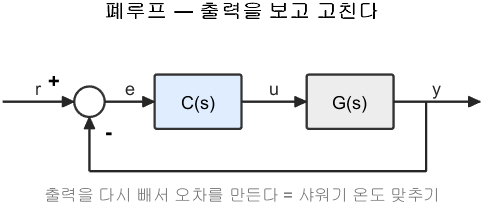

폐루프 — 출력을 보고 고친다

**그림 파일** `loop_closed.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_closed')`

## 1-1. 표 채우기

강의에서 쓴 질량-스프링-댐퍼를 그대로 씁니다.


$$G(s) = \frac{1}{ms^2+bs+k}, \qquad m=1,\; b=0.2,\; k=1$$


할 일

- 아래 코드에서 `TODO` 두 줄만 채우십시오

- 나머지는 다 되어 있습니다

쓸 명령 (전부 강의노트 1부에 있습니다)

- `dcgain(T)` — 정상상태 값

- `stepinfo(T)` — 오버슈트를 포함한 요약

맞았는지 확인하는 법

- 실측 정상상태 값이 $K/(1+K)$ 와 거의 같으면 맞은 것입니다

[G, p] = plant_msd();
K_list = [1 2 5 10 20];

fprintf('   K    정상상태(실측)  이론 K/(1+K)   오버슈트[%%]\n');
fprintf('  ---  --------------  ------------  -----------\n');
for K = K_list
    T   = feedback(K*G, 1);
    ss_ = NaN;    % TODO : dcgain 을 써서 정상상태 값을 구하십시오
    os_ = NaN;    % TODO : stepinfo 를 써서 오버슈트를 구하십시오
    fprintf('  %3d      %7.4f       %7.4f      %7.1f\n', K, ss_, K/(1+K), os_);
end

## 1-2. 답할 것 (두 문장이면 됩니다)

- $K$ 를 키우면 정상상태 오차는 커지는가 작아지는가?

- $K$ 를 키우면 오버슈트는 커지는가 작아지는가?

이 두 답을 합치면 "이득을 키우는 것은 공짜가 아니다" 라는 결론이 나옵니다.

## 2. 기본 — 같은 절차를 DC 모터로

**강의노트 3절과 5절을 그대로 따라 하면 됩니다.** 플랜트만 바뀝니다.

이번 플랜트는 DC 모터의 **속도** 모델입니다.

- `plant_dcmotor('speed')` 로 얻습니다

- 입력은 전압 $[\mathrm{V}]$, 출력은 각속도 $[\mathrm{rad/s}]$

- 목표 각속도는 $r = 10\,\mathrm{rad/s}$ 로 합니다

강의와 딱 하나 다른 점

- 질량-스프링-댐퍼는 $G(0) = 1$ 이었습니다

- 이 모터는 $G(0) \ne 1$ 입니다. 아래에서 직접 확인해 보십시오

[Gm, pm] = plant_dcmotor('speed');
fprintf('\nDC 모터 속도 모델\n');
Gm
fprintf('  G(0) = %.4f\n', dcgain(Gm));
fprintf('  -> 전압 1 V 를 계속 주면 %.2f rad/s 로 돕니다\n\n', dcgain(Gm));

## 2-1. 개루프 — 미리 계산해서 넣기

개루프는 출력을 보지 않고 딱 한 번 계산해서 넣는 방식입니다.

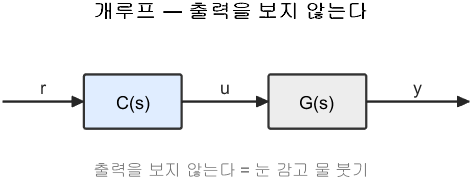

개루프 — 출력을 보지 않는다

**그림 파일** `loop_open.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_open')`

목표 $r$ 을 그대로 얻으려면 입력을 얼마로 주어야 하는가?


$$y = G(0)\,u = r \qquad \Rightarrow \qquad u = \frac{r}{G(0)}$$


그래서 앞에 곱해 주는 상수를 이렇게 정합니다.


$$K_{ff} = \frac{1}{G(0)}$$


할 일 — `TODO` 한 줄만 채우십시오.

r_m   = 10;
Kff_m = NaN;    % TODO : 1/dcgain(Gm) 을 계산하십시오

if ~isnan(Kff_m)
    y_open = step(Kff_m*Gm*r_m, 0:0.01:2);
    fprintf('개루프 : Kff = %.2f , 정상상태 = %.3f rad/s (목표 %.0f)\n', ...
            Kff_m, y_open(end), r_m);
end

## 2-2. 폐루프 — 출력을 보고 고치기

이번에는 비례이득 $K = 50$ 으로 루프를 닫습니다.

그런데 폐루프도 그대로 닫으면 정상상태가 목표에 못 미칩니다. 강의노트 5절에서 본 대로 앞에 보정 상수를 하나 곱해 줍니다.


$$K_r = \frac{1}{T(0)}, \qquad T = \frac{KG}{1+KG}$$


할 일 — `TODO` 한 줄만 채우십시오.

K_m  = 50;
T_m  = feedback(K_m*Gm, 1);
Kr_m = NaN;    % TODO : 1/dcgain(T_m) 을 계산하십시오

if ~isnan(Kr_m)
    fprintf('폐루프 : T(0) = %.4f , Kr = %.3f\n', dcgain(T_m), Kr_m);
end

## 2-3. 두 방법을 한 그림에

코드는 다 되어 있습니다. 위의 `TODO` 두 개를 채우면 그림이 나옵니다.

t_m = (0:0.005:2)';
if ~isnan(Kff_m) && ~isnan(Kr_m)
    y1 = step(Kff_m*Gm*r_m, t_m);
    y2 = step(Kr_m*T_m*r_m, t_m);
    plot(t_m, y1, 'LineWidth', 2); hold on;
    plot(t_m, y2, 'LineWidth', 2);
    yline(r_m, 'k--'); grid on;
    xlabel('시간 [s]'); ylabel('각속도 [rad s^{-1}]');
    legend('개루프', '폐루프 (K = 50)', '목표', 'Location', 'southeast');
    title('DC 모터 속도제어 — 개루프와 폐루프');
end

## 2-4. 답할 것 (세 문장이면 됩니다)

- 구한 $K_{ff}$ 는 얼마인가? 이 값은 **필요한 전압**을 뜻한다. 현실적인가?

- 외란이 없는 지금, 두 응답의 정상상태 값은 같은가 다른가?

- 그렇다면 폐루프를 쓰는 이유는 무엇이겠는가? (강의노트 6절을 떠올려 보라)

## 3. 도전 (선택) — 외란이 다른 자리로 들어오면

**이 문제는 선택입니다. 안 해도 만점입니다.** 가산점 10점입니다.

강의에서는 외란이 **플랜트 입력단**으로 들어왔습니다.


$$y = G\,(u + d)$$


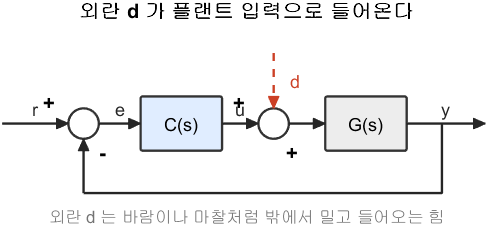

외란 d 가 플랜트 입력으로 들어온다

**그림 파일** `loop_disturbance.png` — `common/dg_loop.m` 의 `dg_loop` · 다시 만들려면 `make_figures('loop_disturbance')`

이번에는 외란이 **출력단**으로 들어오는 경우입니다. 바람이 물체를 직접 밀거나, 센서 뒤에서 값이 더해지는 상황입니다.


$$y = G\,u + d$$


할 일 (하나만 하면 됩니다)

- 출력단 외란에 대한 $y/d$ 를 손으로 유도하라 (두 줄이면 된다)

- MATLAB 으로 확인하라. `feedback(1, K*G)` 를 써 보라

힌트

- 입력단이면 $y/d = \frac{G}{1+KG}$ 였다

- 출력단이면 분자만 바뀐다. 무엇으로 바뀔지 생각해 보라

K_d = 9;
% TODO : 여기에 두세 줄로 확인하십시오

## 채점 기준

- **1. 몸풀기** 30점 — 표를 정확히 채웠는가, 두 질문에 답했는가

- **2. 기본** 70점 — $K_{ff}$, $K_r$ 계산과 그림, 세 질문에 답했는가

- **3. 도전** 가산점 10점 — 유도와 확인

감점 사항 (세 가지뿐입니다)

- 축 이름이나 범례가 없는 그림

- 숫자만 있고 설명이 한 줄도 없는 경우

- 코드가 오류로 멈추는 경우